# Running a Soft Constrained Optimisation with SNOBFit in MATLAB

**Barnaby Walker, James H. Bannock, Adrian M. Nightingale, and John C. de Mello**

In our article, 'Tuning Reaction Products by Constrainted Optimsation', we use the Stable Noisy Optimisation by Branch and Fit algorithm, or SNOBFit, to carry out soft constrained optimisations of a chemical synthesis. For ease of use, we developed a MATLAB class-based wrapper around the original SNOBFit code. The following tutorial will explain how to use this package to run a soft constrained optimisation.

This tutorial is designed to follow on from a more introductory one found in the **'snobfit_tutorial'** file. If you have not done so already, please start with that tutorial.

## RUNNING A SOFT CONSTRAINED OPTIMISATION

To use the package, you first need to import. If you **copy the '+snobfitclass' folder into your MATLAB folder** you can do this simply by calling:

import snobfitclass.*

Otherwise, you will have to make sure that you are in the same folder as the package.

## Creating the SNOBFit Object

The class-based wrapper that we have written is based around a SNOBFit optimisation object. This object has various settings that you can change to set up your experiment, will run the actual optimisation, and will store all of your results.

The first thing you need to do to use it, is create the object:

snobfit_object = snobfitclass.snobclass('name', 'my_first_constrained_snobfit')

User must enter function and setup values!


snobfit_object =   snobclass with properties:

             name: 'my_first_constrained_snobfit'
              fcn: 'none'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: []
        minimised: []
            fbest: []
            xbest: []
            ncall: 100
      termination: 'minimised'


## Setting Up a Constrained Optimisation

As with the normal SNOBFit optimisation, you first need to give the object the name of the objective function to minimise. In this example we will be using a test function defined by the equation:


$$f\left(x_1 ,x_2 \right)=0\ldotp 01x_1^2 +x_2^2$$


where $f\left(x_1 ,x_2 \right)$is the value SNOBFit will try to minimise by calculating it for different values of $x_1$ and $x_2$.

In this example our function is named 'hsf18':

snobfit_object.fcn = 'hsf18'

SNOBFIT experiment has been created!


snobfit_object =   snobclass with properties:

             name: 'my_first_constrained_snobfit'
              fcn: 'hsf18'
    constraintFcn: 'none'
           linked: 0
      constrained: 1
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 10000
      termination: 'minimised'


As well as an objective function, for a constrained optimisation you need to provide the name of the file containing the constraint definitions. The constraint functions that we will be using are:


$$\begin{array}{l}
F_1 \left(x_1 ,x_2 \right):\text{ }{0<\text{ }x}_1 x_2 -25\\
F_2 \left(x_1 ,x_2 \right):\text{ }0<{x_1 }^2 +{x_2 }^2 -25
\end{array}$$


In our example, this constraints file has the same name as our objective function:

snobfit_object.constraintFcn = 'hsf18'

snobfit_object =   snobclass with properties:

             name: 'my_first_constrained_snobfit'
              fcn: 'hsf18'
    constraintFcn: 'hsf18'
           linked: 0
      constrained: 1
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 10000
      termination: 'minimised'


Although this has the same name as the objective function, they are not the same file. Constraint functions are stored in a separate folder in the package's code. For more information on this, and how to define your own function, please read the separate tutorial 'DEFINING STUFF'.

Like the normal SNOBFit optimisation, there are a number of other settings that can be customised, such as the maximum number of function calls or the termination mode:

snobfit_object.ncall = 1000;
snobfit_object.termination = 'minimised';

 For a soft constrained optimisation, it is important to set the bounds of the constraints:

snobfit_object.F_lower = [0, 0]';      % the lower bounds, this problem has two constraints
snobfit_object.F_upper = [Inf, Inf]';  % the upper bounds, this problem has two constraints

As well as the parameter for how hard or soft those constraints are:

snobfit_object.sigma = [1.25, 1.25]';

At this point, we can run our soft constrained SNOBFit optimisation:

SNOBFIT experiment is running...
ncall:	1 to 6
xbest:	21.360000, 7.600000
fbest:	0.238225
ncall:	7 to 12
xbest:	21.360000, 7.600000
fbest:	0.238225
ncall:	13 to 18
xbest:	25.728000, 1.300000
fbest:	0.022392
ncall:	19 to 24
xbest:	25.728000, 1.300000
fbest:	0.022392
ncall:	25 to 30
xbest:	25.728000, 1.300000
fbest:	0.022392
ncall:	31 to 36
xbest:	25.728000, 1.300000
fbest:	0.022392
ncall:	37 to 42
xbest:	25.728000, 1.300000
fbest:	0.022392
ncall:	43 to 48
xbest:	18.576000, 2.100000
fbest:	0.020086
ncall:	49 to 54
xbest:	18.576000, 2.100000
fbest:	0.020086
ncall:	55 to 60
xbest:	18.576000, 2.100000
fbest:	0.020086
ncall:	61 to 66
xbest:	18.576000, 2.100000
fbest:	0.020086
ncall:	67 to 72
xbest:	18.576000, 2.100000
fbest:	0.020086
ncall:	73 to 78
xbest:	18.576000, 2.100000
fbest:	0.020086
ncall:	79 to 84
xbest:	18.576000, 2.100000
fbest:	0.020086
ncall:	85 to 90
xbest:	25.056000, 1.200000
fbest:	0.019350
ncall:	91 to 96
xbest:	25.056000, 1.200000
fbest:	0.019350
ncall:	97 to 102
xbest:	18

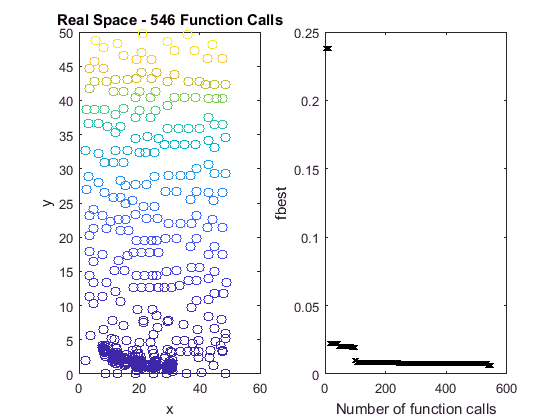

snobfit_object.startExp;

As the optimisation runs, the object prints out the current best function value and the location of that value. It also shows a scatter plot of all the points shown so far, next to a plot of the best function value against the number of function calls. This can help you to visualise your results as the optimisation proceeds, and see if everything is proceeding as it should be.

## ACCESSING YOUR RESULTS

After your optimisation has run, you can access the results directly through the SNOBFit object itself.

To see what the best function value found was:

snobfit_object.fbest

ans = 0.0059

And the location of the best point:

snobfit_object.xbest

ans =    15.5520    1.6500


You can also access the location of best point found within the constraints:

snobfit_object.xcon

ans =    15.8400    1.5500


And the value of of the soft merit function at that point:

snobfit_object.fcon

ans = 0.2323

You can also see all of the parameters that the optimisation tried:

snobfit_object.x

ans =     2.0160    2.0000
   48.7680   13.4000
   33.2640   12.9000
   13.1040   16.6000
   21.3600    7.6000
    7.8720   17.4000
   35.9040   49.6000
    5.5200   48.7000
   22.7520   34.7500
   48.6240   34.5500


And all of the objective function values that these gave:

snobfit_object.f

ans =    1.0e+03 *

    0.0040
    0.2033
    0.1775
    0.2773
    0.0623
    0.3034
    2.4731
    2.3720
    1.2127
    1.2173


All of the constraint function values:

snobfit_object.F

ans =    1.0e+03 *

   -0.0210   -0.0169
    0.6285    2.5329
    0.4041    1.2479
    0.1925    0.4223
    0.1373    0.4890
    0.1120    0.3397
    1.7558    3.7243
    0.2438    2.3772
    0.7656    1.7002
    1.6550    3.5330


And all of the soft merit values:

snobfit_object.fm

ans =     1.9957
    0.5168
    0.4820
    0.5945
    0.2382
    0.6163
    0.9298
    0.9270
    0.8664
    0.8668


As before, you can also visualise this data

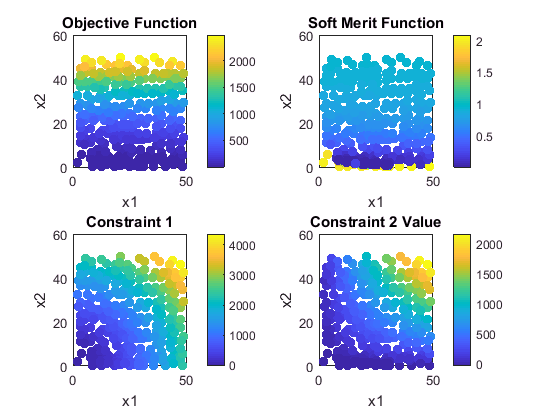

figure
subplot(221)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.f, 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Objective Function')

subplot(222)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.fm, 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Soft Merit Function')

subplot(223)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.F(:,2), 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Constraint 1')

subplot(224)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.F(:,1), 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Constraint 2 Value')

Or you can fit a surface to the data points:

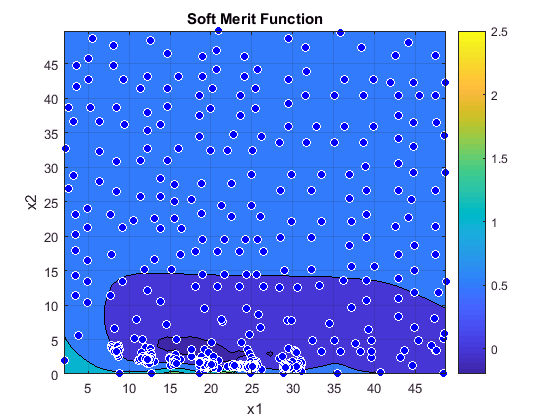

figure;
fitobject = fit(snobfit_object.x, snobfit_object.fm, 'Lowess', 'Normalize', 'on');
plot(fitobject, snobfit_object.x, snobfit_object.fm, 'Style', 'Contour');
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Soft Merit Function')

As well as storing your results on the SNOBFit object itself, the object also saves a copy of itself in a .mat file and the results and a summary of the optimisation in comma-separated (.csv) files in the Results folder on the object's filepath. This means that you can load the SNOBFit object back into MATLAB from the .mat file to access the results or continue the optimisation, even if your computer turns off without you manually saving anything. Saving the results as .csv files also means that you can move these results to any computer and analyse them using whatever analysis software you prefer, such as Python or Excel.